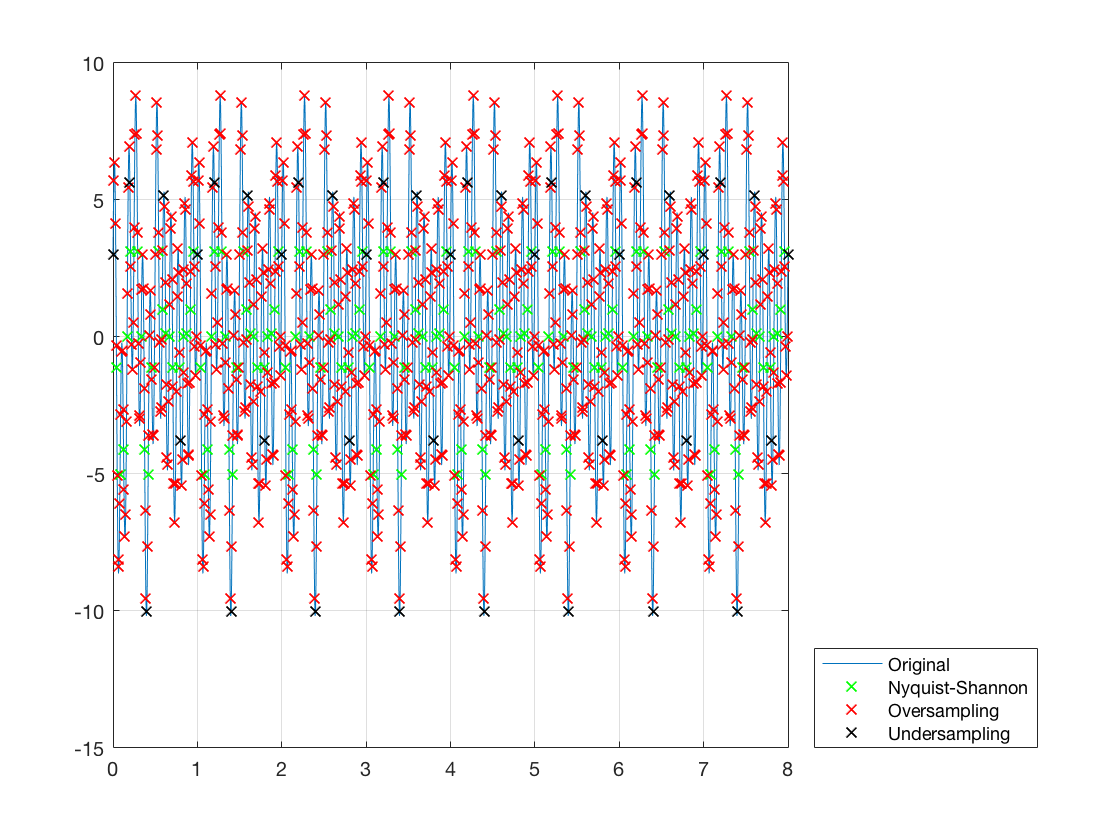

%Nyquist-Shannon sampling frequency: 2*12Hz = 24Hz >= 12Hz;
dt = 1/200; % Sampling rate
dt1 = 1/24; %Nyquist-Shannon sampling rate, double the samples.
dt2 = 1/100; %Oversampling
dt3 = 1/5; %Undersampling
st = 0; % Start time
et = 8; % End time
t = st:dt:et;
t1 = st:dt1:et;
t2 = st:dt2:et;
t3 = st:dt3:et;
y = 5*sin(24*pi*t)+1*cos(12*pi*t)-3*sin(6*pi*t)+2*cos(8*pi*t);
y1 = 5*sin(24*pi*t1)+1*cos(12*pi*t1)-3*sin(6*pi*t1)+2*cos(8*pi*t1);
y2 = 5*sin(24*pi*t2)+1*cos(12*pi*t2)-3*sin(6*pi*t2)+2*cos(8*pi*t2);
y3 = 5*sin(24*pi*t3)+1*cos(12*pi*t3)-3*sin(6*pi*t3)+2*cos(8*pi*t3);
plot(t,y), hold on %plot 
plot(t1,y1,'gx'), grid on
plot(t2,y2,'rx')
plot(t3,y3,'kx'), hold off
legend('Original','Nyquist-Shannon','Oversampling','Undersampling',...
    'location','southeastoutside')